# 蓝牙指纹定位主函数

## 导入指纹数据并进行预处理

if false
    load(['D:\Code\BlueTooth\pos_bluetooth_matlab\Fingerprinting\Data\', ...
        'ble_data_base_least.mat'], 'data');
    data_in = data;
else
    load(['D:\Code\BlueTooth\pos_bluetooth_matlab\Fingerprinting\Data\', ...
        'ble_data_base_least_completion.mat'], 'data_new');
    data_in = data_new;
end

% ble_data_base_least_completion
% 2.数据预处理
% 调用cell2mat转换完之后的数据格式:
% ['Beacon0','Beacon1','Beacon6','Beacon7','POS_X','POS_Y']
% [-66,-42,-62,-65,0,0]
data_mat = cell2mat(data_in);
ble_figureprinting_train = data_mat(:, 1:4); % 特征数据
ble_labels_train = strings(0);

% 将数组坐标[x,y]转换为字符串坐标"x:x-y:x"
for k = 1:1:length(ble_figureprinting_train)
    ble_labels_train(k) = strcat("x:", num2str(data_mat(k, 5)), ...
        ",", "y:", num2str(data_mat(k, 6)));
end

ble_labels_train = reshape(ble_labels_train, ...
    [length(ble_labels_train), 1]);

## knnsearch lose rate 验证

% lose rate
losr_rate = zeros(0);

for k = 1:20
    n_neigherbors = k;
    rng(100);
    Mdl = fitcknn(ble_figureprinting_train, ble_labels_train, 'NumNeighbors', n_neigherbors);
    loss = resubLoss(Mdl);
    losr_rate(k) = loss;
    rng(10); % For reproducibility
    CVMdl = crossval(Mdl, 'KFold', 5);
    kloss = kfoldLoss(CVMdl);
end

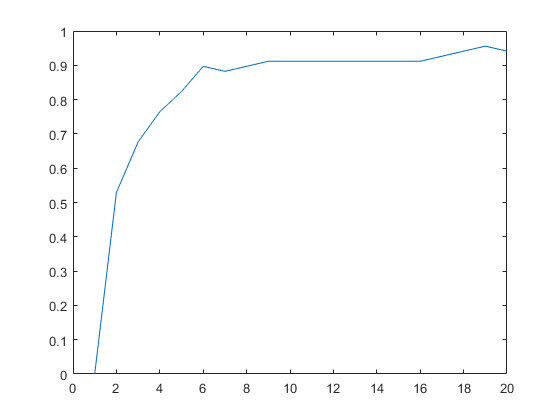

figure('Name','sd')
plot(1:1:20,losr_rate)

## Kd-Tree验证